% simulatePBS_scalar.m
% Simulate four “pads” in a PBS‐filled petri dish
% using the frequency‐domain scalar PDE approach.

%% 1) Parameters
f     = 1000;                % stimulation frequency [Hz]
omega = 2*pi*f;            % angular frequency [rad/s]
R     = 45;             % dish radius [m]
re    = 1e-1;              % pad radius [m]
sigma = 1.5;               % PBS conductivity [S/m]
eps0  = 8.8541878128e-12;  % vacuum permittivity [F/m]

% Voltages of StimSignal (amplitude [V])
A = [5, 3, 0, 0];
% Phase of StimSignal (phase [rad])
phi = [0, pi, 0, 0];

%Impedances of Acq Circuit
Rs = 60e3;              % 60 kΩ
Ze = 800e3;  
% 2 MΩ
% Effective pad voltages after going through the resistance
Vpad = A %* (Ze/(Rs+Ze));  

Vpad =      5     3     0     0


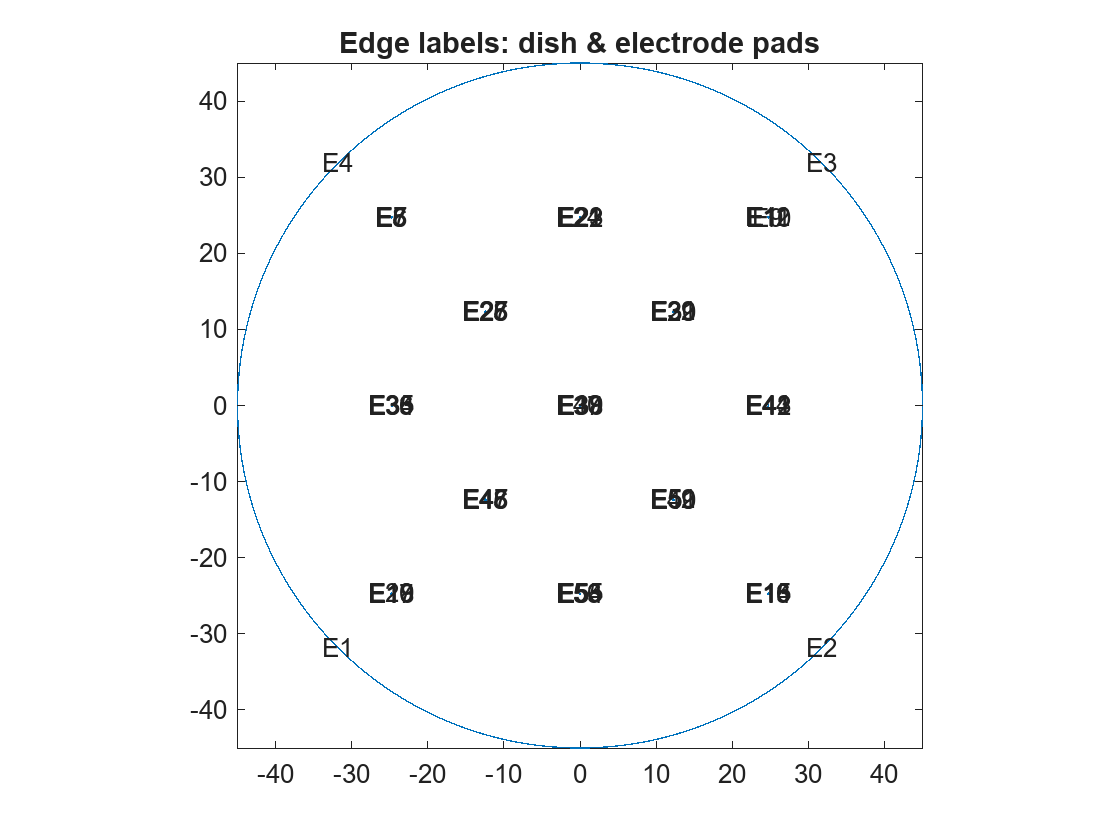

% Currents flowing *through* the series resistor (and into the Electrode and PBS)
%Iseries = A./(Rs+Ze);  
% (same as Vpad/Ze)

% Raw pad positions from bottom‐left in cm
dishCtr_cm  = [4.5, 4.5];          % dish center in cm

pads_cm_raw = [2.025, 6.975;   % Electrode (Diagram -- A)
               6.975, 6.975;   % Electrode (Diagram -- B)
               6.975, 2.025;   % Electrode (Diagram -- C)
               2.025, 2.025;   % Electrode (Diagram -- D)
               4.50, 6.975;   % Measuring Point -- 3
               3.26, 5.73;   % Measuring Point -- 4
               5.73, 5.73;   % Measuring Point -- 5
               2.025, 4.50;   % Measuring Point -- 6
               4.50, 4.50;   % Measuring Point -- 7
               6.975, 4.50;   % Measuring Point -- 8
               3.26, 3.26;   % Measuring Point -- 9
               5.73, 3.26;   % Measuring Point -- 10
               4.50, 2.025];   % Measuring Point -- 11

% Recenter to dish‐center and convert to meters
pads_cm_centered = pads_cm_raw - dishCtr_cm;
centers = pads_cm_centered * 10;  % 4×2 array [m]

%% 2) Build geometry: big dish minus 4 pad-holes
model2 = createpde(1);  % scalar PDE

% 2a) Prepare decsg inputs
N = size(centers,1);
gd = [1;0;0;R];
for k=1:N
    gd(:,end+1) = [1; centers(k,1); centers(k,2); re];
end

names = cell(1,N+1);
names{1} = 'C1';
for k=1:N
    names{k+1} = sprintf('E%d',k);
end

L = max(cellfun(@length,names));
ns = repmat(' ',L,N+1);
for k=1:N+1
    nm = names{k};
    ns(1:length(nm),k) = nm;
end

sf = names{1};
for k=2:N+1
    sf = [sf '-' names{k}];
end

% 2b) Import geometry
[g,bt] = decsg(gd,sf,ns);
geometryFromEdges(model2,g);

% — 2c) Quick plot to read edge IDs (outer dish + each pad) —
figure;
pdegplot(model2,'EdgeLabels','on');
axis equal tight;
title('Edge labels: dish & electrode pads');


% pre-3) Group the edges for each pad (dish edges are 1:4, pads are 5:8,9:12,…)
padEdges = cell(1,N);
for k=1:N
    padEdges{k} = (4*k+1) : (4*k+4);
end

padEdges %Visualize the pads

padEdges = 1×13 cell array
    {[5 6 7 8]}    {[9 10 11 12]}    {[13 14 15 16]}    {[17 18 19 20]}    {[21 22 23 24]}    {[25 26 27 28]}    {[29 30 31 32]}    {[33 34 35 36]}    {[37 38 39 40]}    {[41 42 43 44]}    {[45 46 47 48]}    {[49 50 51 52]}    {[53 54 55 56]}



%% 3) PDE coefficients: solve ∇·(c∇V)=0 with c = σ + jωε0
cval = sigma + 1j*omega*eps0;
specifyCoefficients(model2, ...
    'm',0, 'd',0, ...
    'c',cval, ...
    'a',0, 'f',0);

%% 4) Boundary conditions: explicit pad-to-voltage map

% Define a cell array where each row is {padIndex, amplitude[V], phase[rad]}
% Omit rows for any pad you want left floating.
config = {
   6,  Vpad(1),    phi(1);    % pad 1 → V @ ° 
   7,  Vpad(2),    phi(2);    % pad 2 → V @ °
   %3,  Vpad(3),    phi(3);    % pad 3 → V @ º
   %13, Vpad(4),    phi(4);   % pad 4 → V @ º
   %9, 0,          0;        %GND
};

% Apply exactly one Dirichlet BC per row of that table
for i = 1:size(config,1)
    padIdx = config{i,1};      % which pad
    A      = config{i,2};      % amplitude
    phi    = config{i,3};      % phase
    
    Vk = A*exp(1j*phi);
    applyBoundaryCondition(model2, ...
        'dirichlet', ...
        'Edge', padEdges{padIdx}, ...
        'u',    Vk);
end

%% 5) Mesh and solve
%generateMesh(model2,'Hmax',1e-3);
%% 5) Mesh with local refinement on electrode edges
% 5a) Global maximum element size
hGlobal = 1;     % 1 mm everywhere

% 5b) Electrode edge IDs
electrodeEdges = horzcat(padEdges{:});   % all the pad‐boundary arcs

% 5c) Desired max element size *on* those edges
hPad = 2e-1;        % 0.2 mm on the pad arcs

% 5d) Generate mesh
mesh = generateMesh(model2, ...
    'Hmax' , hGlobal, ...
    'Hedge', {electrodeEdges, hPad});
results = solvepde(model2);

figure;
pdeplot(model2, ...
    'XYData', abs(results.NodalSolution), ...
    'Contour','on', ...
    'Mesh','off');

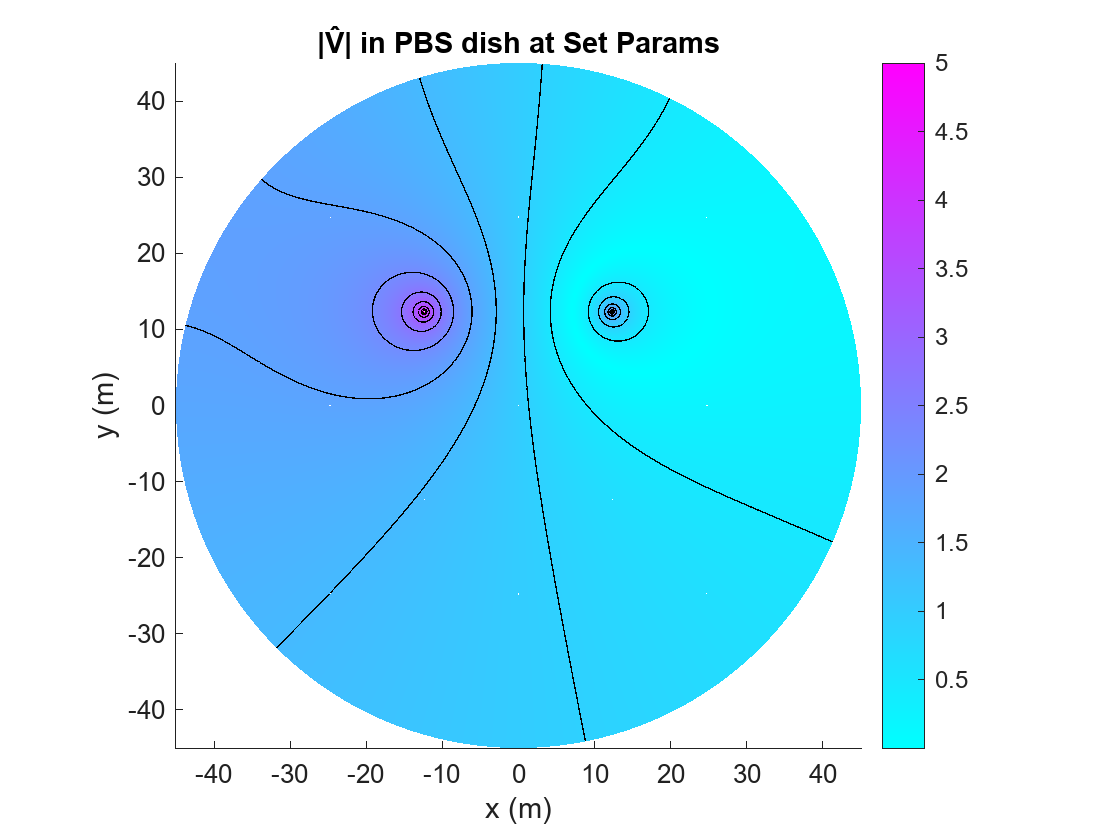

axis equal tight;
colorbar;
title('|V̂| in PBS dish at Set Params');
xlabel('x (m)'); ylabel('y (m)');

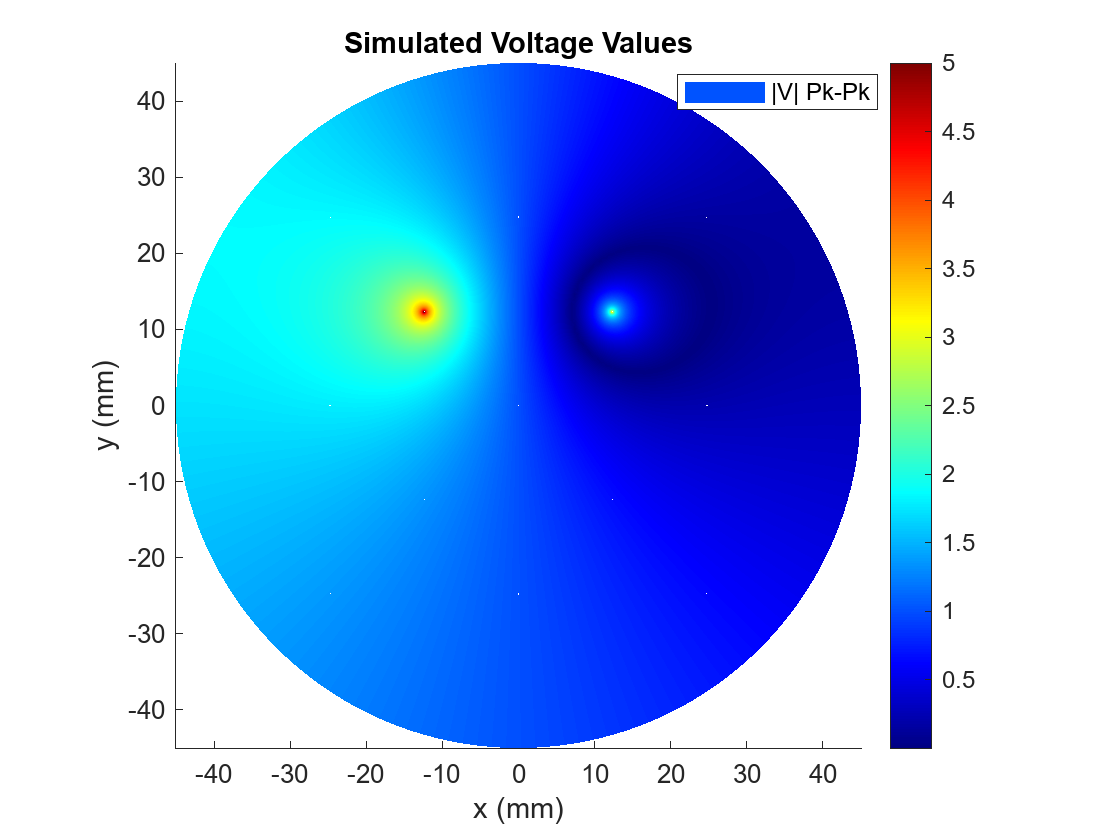


pdeplot(model2, ...
  'XYData',abs(results.NodalSolution), ...
  'Mesh','off');
axis equal tight; colormap(jet);
title('Simulated Voltage Values');
xlabel('x (mm)'); ylabel('y (mm)');
legend('|V| Pk-Pk','Location','best');

%% 6) Plot |V̂| with patch + custom data‐tip to show voltage






% extract node coordinates and solution
nodes = model2.Mesh.Nodes;      % 2×N array
u    = abs(results.NodalSolution);

% your query points, one per row:
queryPts = centers

queryPts =   -24.7500   24.7500
   24.7500   24.7500
   24.7500  -24.7500
  -24.7500  -24.7500
         0   24.7500
  -12.4000   12.3000
   12.3000   12.3000
  -24.7500         0
         0         0
   24.7500         0


% preallocate
numPts = size(queryPts,1);
u_atPts = zeros(numPts,1);

for k = 1:numPts
    xq = queryPts(k,1);
    yq = queryPts(k,2);
    % compute squared distance to all nodes
    dist2 = (nodes(1,:)-xq).^2 + (nodes(2,:)-yq).^2;
    [~, idx] = min(dist2);
    u_atPts(k) = u(idx);
end

% build table
T = table( queryPts(:,1), queryPts(:,2), u_atPts, ...
           'VariableNames', {'x','y','|V|'} )

T = 13×3 table
      x         y         |V|  
    ______    ______    _______

    -24.75     24.75     1.8469
     24.75     24.75    0.14859
     24.75    -24.75    0.63623
    -24.75    -24.75     1.3625
         0     24.75    0.98766
     -12.4      12.3          5
      12.3      12.3          3
    -24.75         0     1.7824
         0         0     1.0095
     24.75         0    0.21824
     -12.4     -12.4     1.3399
      12.3     -12.4    0.66843
         0    -24.75    0.99659


disp(T)

      x         y         |V|  
    ______    ______    _______

    -24.75     24.75     1.8469
     24.75     24.75    0.14859
     24.75    -24.75    0.63623
    -24.75    -24.75     1.3625
         0     24.75    0.98766
     -12.4      12.3          5
      12.3      12.3          3
    -24.75         0     1.7824
         0         0     1.0095
     24.75         0    0.21824
     -12.4     -12.4     1.3399
      12.3     -12.4    0.66843
         0    -24.75    0.99659



Tpk_pk = table( queryPts(:,1), queryPts(:,2), 2*u_atPts, ...
           'VariableNames', {'x','y','|V|'} )

Tpk_pk = 13×3 table
      x         y         |V|  
    ______    ______    _______

    -24.75     24.75     3.6938
     24.75     24.75    0.29717
     24.75    -24.75     1.2725
    -24.75    -24.75     2.7251
         0     24.75     1.9753
     -12.4      12.3         10
      12.3      12.3          6
    -24.75         0     3.5649
         0         0     2.0191
     24.75         0    0.43648
     -12.4     -12.4     2.6798
      12.3     -12.4     1.3369
         0    -24.75     1.9932


disp(Tpk_pk)

      x         y         |V|  
    ______    ______    _______

    -24.75     24.75     3.6938
     24.75     24.75    0.29717
     24.75    -24.75     1.2725
    -24.75    -24.75     2.7251
         0     24.75     1.9753
     -12.4      12.3         10
      12.3      12.3          6
    -24.75         0     3.5649
         0         0     2.0191
     24.75         0    0.43648
     -12.4     -12.4     2.6798
      12.3     -12.4     1.3369
         0    -24.75     1.9932



%Esta tabla --> mi config
%1 --> 1 --> 0.312
%2 --> 3 --> 0.272
%3 --> 13 --> 0.256
%4 --> 11 --> 0.280
%5 --> 2 --> 0.280
%6 --> 4 --> Stim (0.7/0)
%7 --> 5 --> Stim (0.3/pi)
%8 --> 6 --> 0.3
%9 --> 7 --> 0.296
%10 --> 8 --> 0.272
%11 --> 9 --> 0.280
%12 --> 10 --> 0.280
%13 --> 12 --> 0.280

% — your existing table
ID    = (1:13)';
Value = [ "3.84"
          "2.64"
          "2.70"
          "2.64"
          "2.88"
          "Stim (5/0)"
          "Stim (3/pi)"
          "3.20"
          "2.72"
          "2.64"
          "2.72"
          "2.64"
          "2.72" ];
T_exp = table(ID, Value, 'VariableNames', {'ID','Value'});

% 1) convert the Value column from string→double
T_exp.Value = str2double( T_exp.Value );

% 2) remove the two stim rows (they’re now NaN)
T_exp( isnan(T_exp.Value), : ) = [];

% 3) if you like, reset ID to 1:11
T_exp.ID = (1:height(T_exp))';

% check
disp(T_exp)

    ID    Value
    __    _____

     1    3.84 
     2    2.64 
     3     2.7 
     4    2.64 
     5    2.88 
     6     3.2 
     7    2.72 
     8    2.64 
     9    2.72 
    10    2.64 
    11    2.72 



% 1) extract the numeric “|v|” data
vals = Tpk_pk{:,3};            

% 2) build a new table with an ID column
T_sim = table((1:numel(vals))', vals, ...
           'VariableNames', {'ID','Value'});

% 3) display it
disp(T_sim)

    ID     Value 
    __    _______

     1     3.6938
     2    0.29717
     3     1.2725
     4     2.7251
     5     1.9753
     6         10
     7          6
     8     3.5649
     9     2.0191
    10    0.43648
    11     2.6798
    12     1.3369
    13     1.9932



% ——————————————————————————————————————————————
% 0. Assume you already have your two 13×2 tables in workspace:
%    T_exp   (experimental)   with variables {'ID','Value'}
%    T_sim   (simulation)     with variables {'ID','Value'}

% 1. Remove stimulation rows (IDs 6 and 7)
removeIDs = [6 7];
%T_exp(ismember(T_exp.ID, removeIDs), :) = [];
T_sim(ismember(T_sim.ID, removeIDs), :) = [];
disp(T_sim)

    ID     Value 
    __    _______

     1     3.6938
     2    0.29717
     3     1.2725
     4     2.7251
     5     1.9753
     8     3.5649
     9     2.0191
    10    0.43648
    11     2.6798
    12     1.3369
    13     1.9932



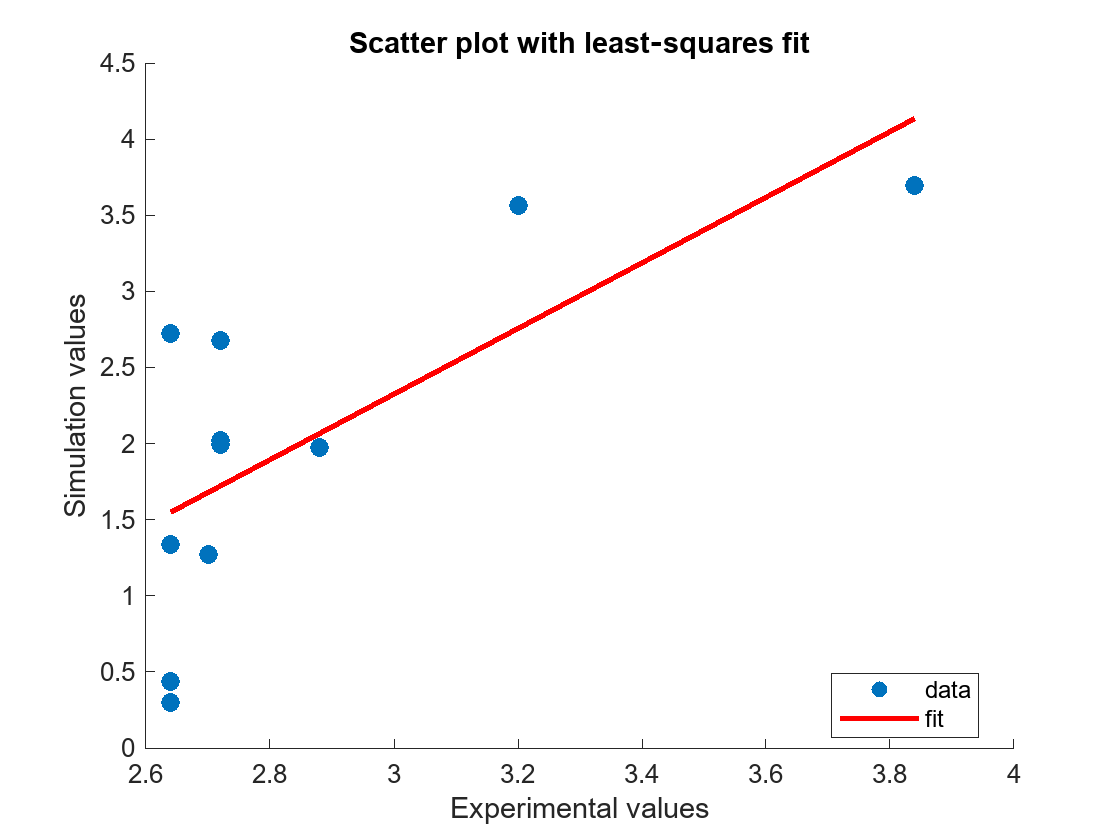


% (Optionally reset ID to 1:11)
%T_exp.ID = (1:height(T_exp))';
T_sim.ID = (1:height(T_sim))';

% 2. Extract the 11×1 numeric vectors
exp_vals = T_exp.Value;
sim_vals = T_sim.Value;

%Scatter Plot
figure('Name','Exp vs Sim Scatter');
scatter(exp_vals, sim_vals, 50, 'filled');
hold on

% 1) compute slope and intercept “by hand”
x = exp_vals(:);
y = sim_vals(:);
xm = mean(x);
ym = mean(y);

% slope m and intercept b
m = sum( (x - xm).*(y - ym) ) / sum( (x - xm).^2 );
b = ym - m*xm;

% 2) build a smooth line over the data range
xfit = linspace(min(x), max(x), 100);
yfit = m*xfit + b;

% 3) plot the fit
plot(xfit, yfit, 'r-', 'LineWidth', 2);

hold off
xlabel('Experimental values');
ylabel('Simulation values');
title('Scatter plot with least‐squares fit');
legend('data','fit','Location','best')



[R, P] = corrcoef(exp_vals, sim_vals);
fprintf('Pearson r = %.3f   (p = %.3f)\n', R(1,2), P(1,2));

Pearson r = 0.706   (p = 0.015)



% 4. Bias, RMSE, MAE
diffs = exp_vals - sim_vals;
bias = mean(diffs);
rmse = sqrt(mean(diffs.^2));
mae  = mean(abs(diffs));
fprintf('Bias = %.3f\n', bias);

Bias = 0.850


fprintf('RMSE = %.3f\n', rmse);

RMSE = 1.209


fprintf('MAE  = %.3f\n', mae);

MAE  = 0.931


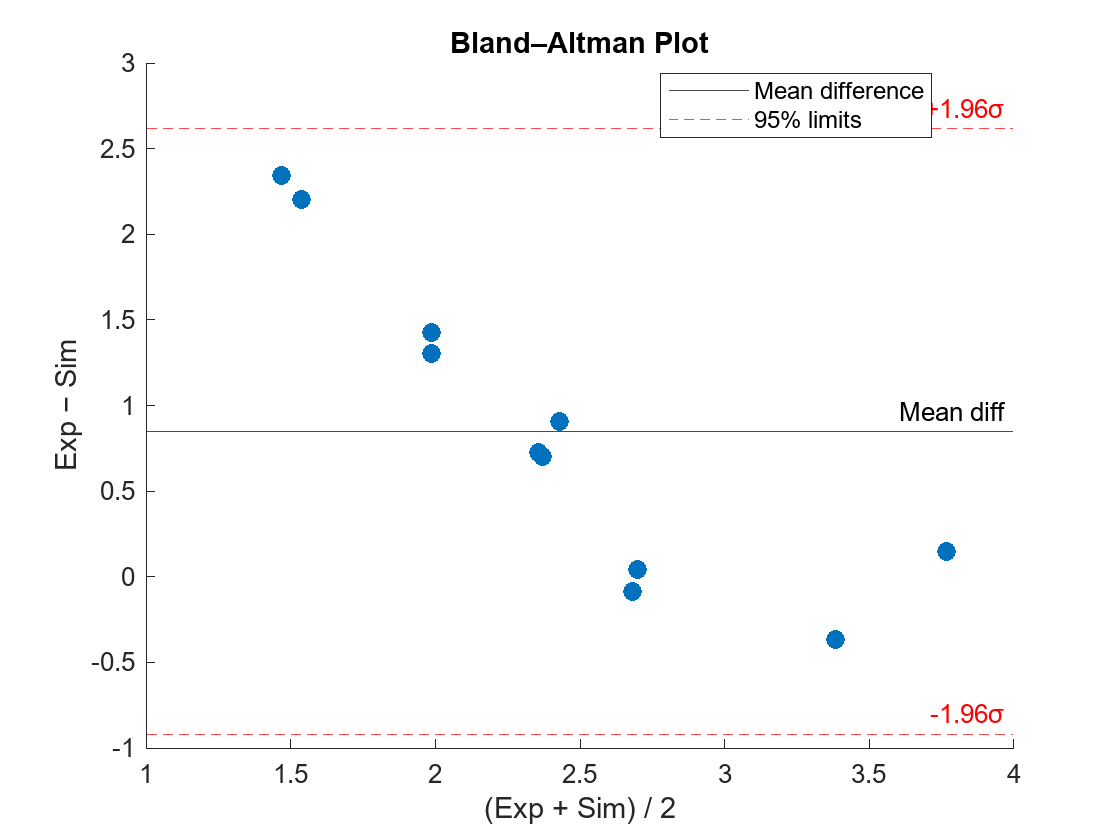


% 5. Bland–Altman plot
means = (exp_vals + sim_vals) / 2;
sd    = std(diffs);

figure('Name','Bland–Altman');
scatter(means, diffs, 50, 'filled');
hold on;
h_mean = yline(bias,      'k-',  'Mean diff');
h_lo   = yline(bias-1.96*sd, 'r--','-1.96σ');
h_hi   = yline(bias+1.96*sd, 'r--','+1.96σ');
hold off;
xlabel('(Exp + Sim) / 2');
ylabel('Exp − Sim');
title('Bland–Altman Plot');
legend([h_mean h_hi], 'Mean difference','95% limits','Location','best');

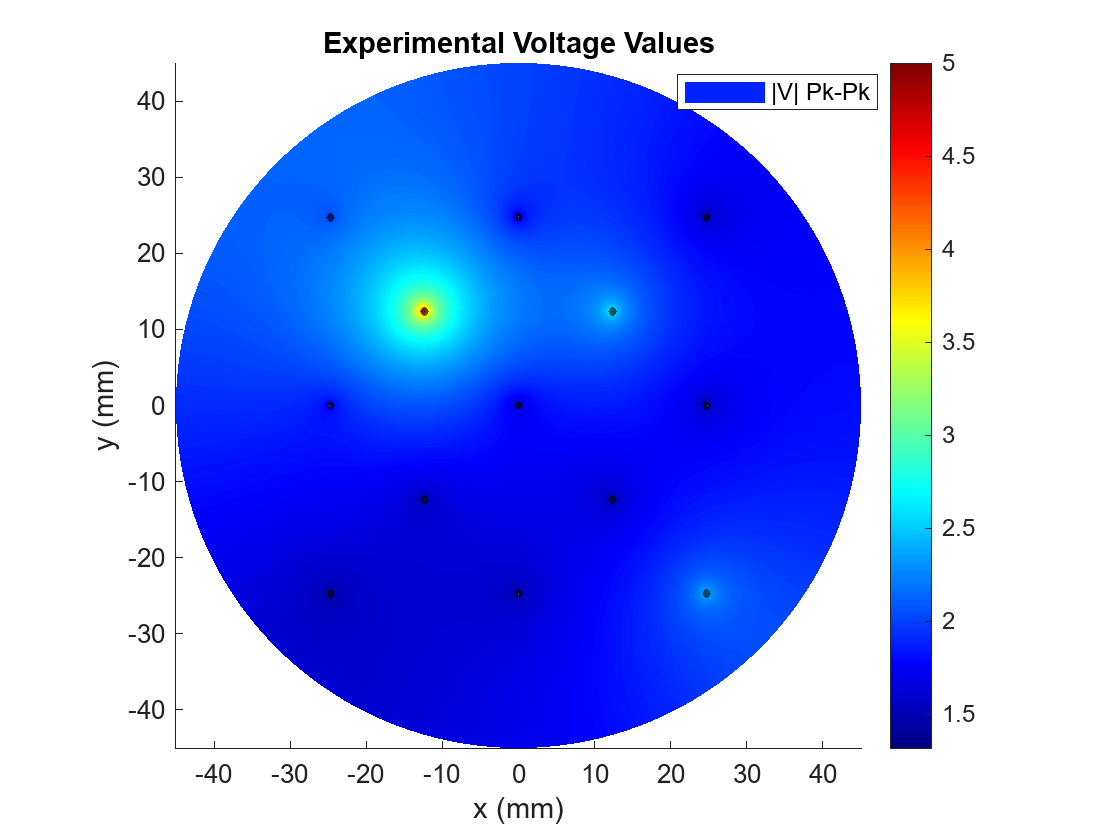

% your pad‐center data
xp_all = [ -24.75,   24.75,   24.75,  -24.75,    0,      -12.4,   12.3,  -24.75,    0,       24.75,  -12.4,   12.3,    0 ];
yp_all = [  24.75,   24.75,  -24.75,  -24.75,  24.75,    12.32,   12.3,      0,      0,         0,   -12.4,  -12.4,  -24.75 ];
%Vp = [  0.312/2,  0.272/2,  0.256/2, 0.280/2, 0.280/2,     0.7,     0.3,      0.3/2,  0.296/2,   0.272/2, 0.280/2,  0.280/2,  0.280/2 ];

xp = [ -24.75,   24.75,   24.75,  -24.75,    0,      -12.4,   12.3,  -24.75,    0,       24.75,  -12.4,   12.3,    0 ];
yp = [  24.75,   24.75,  -24.75,  -24.75,  24.75,    12.32,   12.3,      0,      0,         0,   -12.4,  -12.4,  -24.75 ];
Vp = [  3.84/2,  2.64/2,  2.70, 2.64/2, 2.88/2,     5,     3,  3.20/2,  2.72/2, 2.64/2, 2.72/2,  2.64/2,  2.72/2 ];

% X and Y coordinates for CONFIG 3 TIS
%xp = [ 24.75,   24.75,  -24.75,    0,      -12.4,   12.3,  -24.75,    0,       24.75,     12.3,    0 ];
%yp = [ 24.75,  -24.75,  -24.75,  24.75,    12.3,   12.3,      0,      0,         0,     -12.4,  -24.75 ];
%Vp = [ 0,          0.723,    0.706,   0.762,   0.802,     0.673, 0.842,  0.708,       0,      0.747,  0.720 ];

% X and Y coordinates for CONFIG 2 TIS
%xp = [ -24.75,   24.75,   24.75,  -24.75,    0,      -12.4,   12.3,      0,         -12.4,   12.3,    0 ];
%yp = [  24.75,   24.75,  -24.75,  -24.75,  24.75,    12.32,   12.3,       0,         -12.4,  -12.4,  -24.75 ];
%Vp = [  0.877,    0.888,    0.952,    0.957,     0,       0.896,     0.924,     1.08,   0.939,    0.947,     0 ];

% X and Y coordinates for CONFIG 1 TIS
%xp = [  24.75,  -24.75,    0,      -12.4,   12.3,  -24.75,    0,       24.75,  -12.4,   12.3,    0 ];
%yp = [ -24.75,  -24.75,  24.75,    12.32,   12.3,      0,      0,         0,   -12.4,  -12.4,  -24.75 ];
%Vp = [  0,        0,       0.281,     0.251,     0.180,   0.165,   0.137,     0.125,    0.213,    0.188,    0.160 ];


R     = 45;    % dish radius
rPad  = 0.1;   % electrode radius

% 1a) build the geometry description matrix `gd`
%    first column is the big dish, then one column per pad
gd = zeros(4, 1+numel(xp));
gd(:,1) = [1; 0; 0; R];             % “1; x0; y0; R” for the big circle
for k=1:numel(xp)
    gd(:,1+k) = [1; xp(k); yp(k); rPad];
end

% 1b) name‐space: we need one two‐letter name per column
%     (‘D1’ for disk, then ‘P1’…‘P13’ for pads)
names = ["D1", ...                          % disk
         arrayfun(@(i) sprintf("P%d",i), 1:numel(xp), 'uni', true)];
namesCell  = cellstr(names);          % now a 14×1 cell of 1×2 char vectors
ns         = char(namesCell)';        % char(...) → 14×2, then ' → 2×14
% 1c) set the set‐formula: “D1 minus union of all P’s”
padList = strjoin(arrayfun(@(i) ['P' num2str(i)], 1:numel(xp), 'uni',false), '+');
setFormula = sprintf('D1-(%s)', padList);

% 1d) decompose and load geometry
[gdl, ~] = decsg(gd, setFormula, ns);
model34 = createpde();
geometryFromEdges(model34, gdl);

sigmaPBS = 1.5;
specifyCoefficients(model34, ...
    'm',0, 'd',0, ...
    'c',sigmaPBS, ...
    'a',0, 'f',0 );
generateMesh(model34,'Hmax',R/50);

% --- find which geometric edges correspond to each pad ----
numE = model34.Geometry.NumEdges;
padEdges = zeros(size(xp));   % to hold the matching edge ID per pad

for e = 1:numE
    % get the mesh‐node indices on edge e
    ne = findNodes(model34.Mesh, 'region', 'Edge', e);
    if isempty(ne), continue; end

    % compute the "midpoint" of that edge from its mesh nodes
    edgeMid = mean(model34.Mesh.Nodes(:, ne), 2);  % [x; y]

    % see if this midpoint is close to any pad center
    for k = 1:numel(xp)
        if norm(edgeMid - [xp(k); yp(k)]) < rPad*1.1
            padEdges(k) = e;
        end
    end
end

% sanity check
assert(all(padEdges>0), 'Could not locate one or more pad edges!');

% --- now apply a Dirichlet BC on each pad‐edge ----
for k = 1:numel(xp)
    applyBoundaryCondition(model34, ...
        'dirichlet', ...
        'Edge', padEdges(k), ...
        'u',    Vp(k) );
end

results = solvepde(model34);
figure;
pdeplot(model34, ...
  'XYData',abs(results.NodalSolution), ...
  'Mesh','off');
axis equal tight; colormap(jet);
title('Experimental Voltage Values');
xlabel('x (mm)'); ylabel('y (mm)');
hold on;
scatter( xp_all, yp_all, ...         % your pad-centers
         10, ...             % much smaller size (try 10–30)
         'k', ...            % black color
         'filled', ...
         'MarkerEdgeColor','none', ...      % no white outline
         'MarkerFaceAlpha',0.6 );           % lightly transparent
legend('|V| Pk-Pk','Location','best');